clear variables;
addPath;

%tempo reduction param
para.kF = 20;
para.redL = 5;
para.reduct = true;

%ACA param
para.nMi = 5;
para.nMa = 10;
para.ini='r';
para.k=8;
para.nIni=1;

%HACA param
para2 = para;
para2.nMi = 4;
para2.nMa = 8;
para2.k=4;
para2.nIni=10;
paraH = [para para2];

%output path
out_path = './output/';
%mkdir(out_path);

%select cluster num
sel_num = 2;

## ACA on Select data (mice) and select clusters

 9347 -> 2561
 8247 -> 2093
 10331 -> 2683
 10046 -> 2729


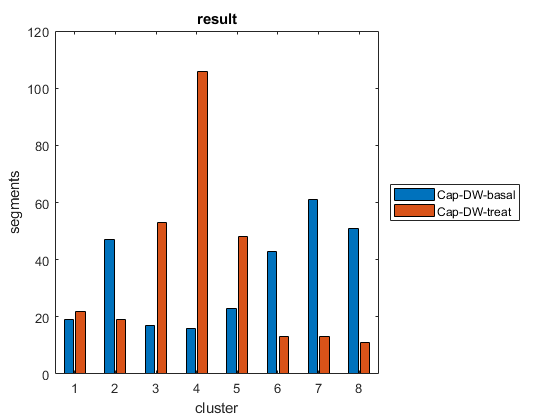

 11875 -> 3020
 9843 -> 2331
 11097 -> 2960
 9270 -> 2381
 8935 -> 2640
 9337 -> 2377
 9188 -> 2528
 9259 -> 2207
 9720 -> 2756
 9665 -> 2601
 9562 -> 2653
 9338 -> 2510
 10194 -> 2960
 8529 -> 2330


all_paths = getAllFile('../feat/20210811/');

nX = [];
ns = [];
splits = [];
nnames = [];

% multiple
micenames = {'B' , 'DW', 'LKB', 'LW', 'RK', 'SW', 'LKW' , 'MW', 'WT'};
for i=1:size(micenames,2)
    % data process
    micename = micenames{i};
    sel = find(contains(all_paths, ['-',micename,'-']));
    paths=all_paths(sel);
    [X, ends, names] = loadData(paths,para);
    nnames = [nnames, names];
    % aca
    K = conKnl(conDist(X, X));
    seg = segIniR(K, para);
    segResult = segAca(K, para, seg);
    % plot result
    [sP, LP, ss, labels] = segPart(segResult.s,segResult.G,ends);
    clusterPlot(labels,names,strcat(out_path,micename,'.png'));
    % select and append 
    sel = largeDiff(labels,sel_num,'scale2');
    [cX,cs,csplits] = selectCluster(X,segResult.s,segResult.G,sel,ends);
    [nX,ns,splits] = concateSel(nX,ns,splits,cX,cs,csplits);
    
end

## Recluster

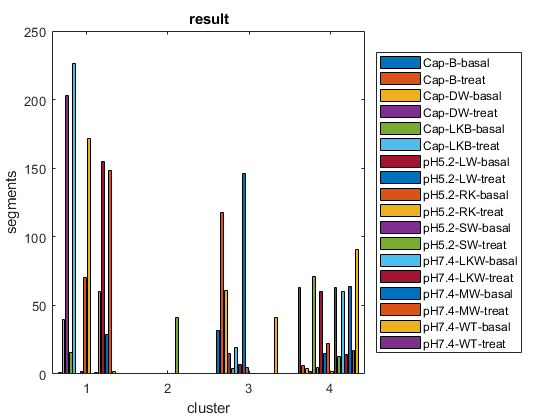

nseg = reCluster(nX,ns,4);
ends = [1 ns(splits(1:end-1))];
ends = [ends ns(end)];
[sP, LP, ss, labels] = segPart(nseg.s,nseg.G,ends);
% clusterPlot(labels,nnames,strcat(out_path,'recluster.png'));
clusterPlot(labels,nnames,[]);

clusterPlot(labels(:,[14,16,18]),nnames([14,16,18]),strcat(out_path,'recluster4_ph74.png'));